clear; clc;
cd ~/git/hardDiskControl/discreteTimeControl/
load ../data/sysDT.mat
load ../data/Gz.mat
load ../data/ppPoles.mat

riseTime = 0.052333; %seconds
Ts = riseTime/10;

figure('Position',[0 0 1000 1000]); clf; hold on;

Q = diag([0 0 2E3 1E8]);
R = [0];
[X,Klqr,~] = idare(sysDT.A,sysDT.B,Q,R);
sysLQR = ss(sysDT.A-sysDT.B*Klqr,sysDT.B,sysDT.C,sysDT.D,Ts);
sysLQR.B = sysLQR.B*dcgain(sysLQR)^-1;

step(sysLQR)

Q = diag([0 0 2E3 1E8]);
R = [3.4E-9];
[X,Klqr,~] = idare(sysDT.A,sysDT.B,Q,R);
sysSat = ss(sysDT.A-sysDT.B*Klqr,sysDT.B,sysDT.C,sysDT.D,Ts);
sysSat.B = sysSat.B*dcgain(sysSat)^-1;

step(sysSat); grid on;
info = stepinfo(sysSat);
info.Overshoot

ans = 4.2992

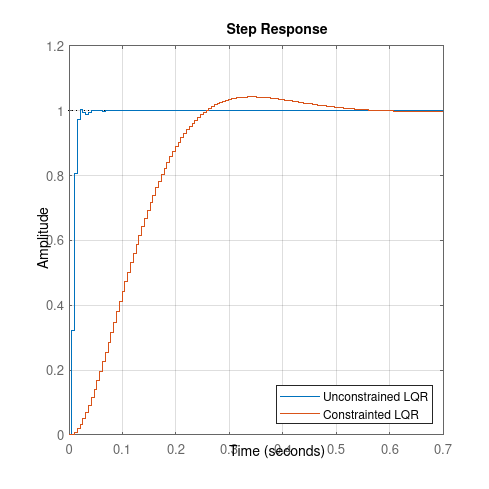


legend('Unconstrained LQR','Constrainted LQR','Location','southeast')

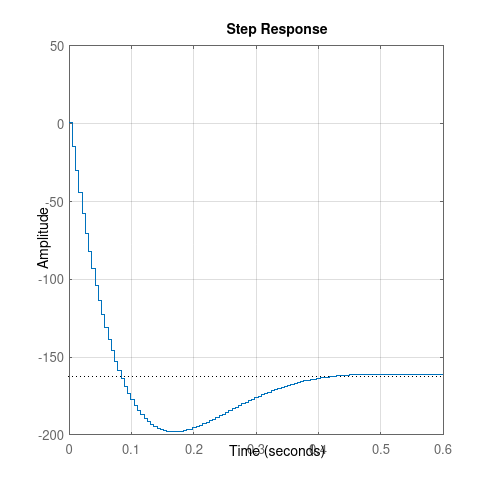



figure('Position',[0 0 1000 1000]); clf; hold on;
sysSat = ss(sysSat.A,sysSat.B,-Klqr,1,Ts);
step(sysSat); grid on;

uMaxGain = max(abs(step(sysSat)))

uMaxGain = 198.0022